%***************************************
%Author: Chaoqun Wang
%Date: 2019-10-15
%***************************************

## 流程初始化

clear all; close all;
x_I=1; y_I=1;           % 设置初始点
x_G=700; y_G=700;       % 设置目标点
Thr=50;                 %设置目标点阈值
Delta= 30;              % 设置扩展步长

## 建树初始化

T.v(1).x = x_I;         % T是我们要做的树，v是节点，这里先把起始点加入到T里面来
T.v(1).y = y_I; 
T.v(1).xPrev = x_I;     % 起始节点的父节点仍然是其本身
T.v(1).yPrev = y_I;
T.v(1).dist=0;          %从父节点到该节点的距离，这里可取欧氏距离
T.v(1).indPrev = 0;     %

## 开始构建树——作业部分

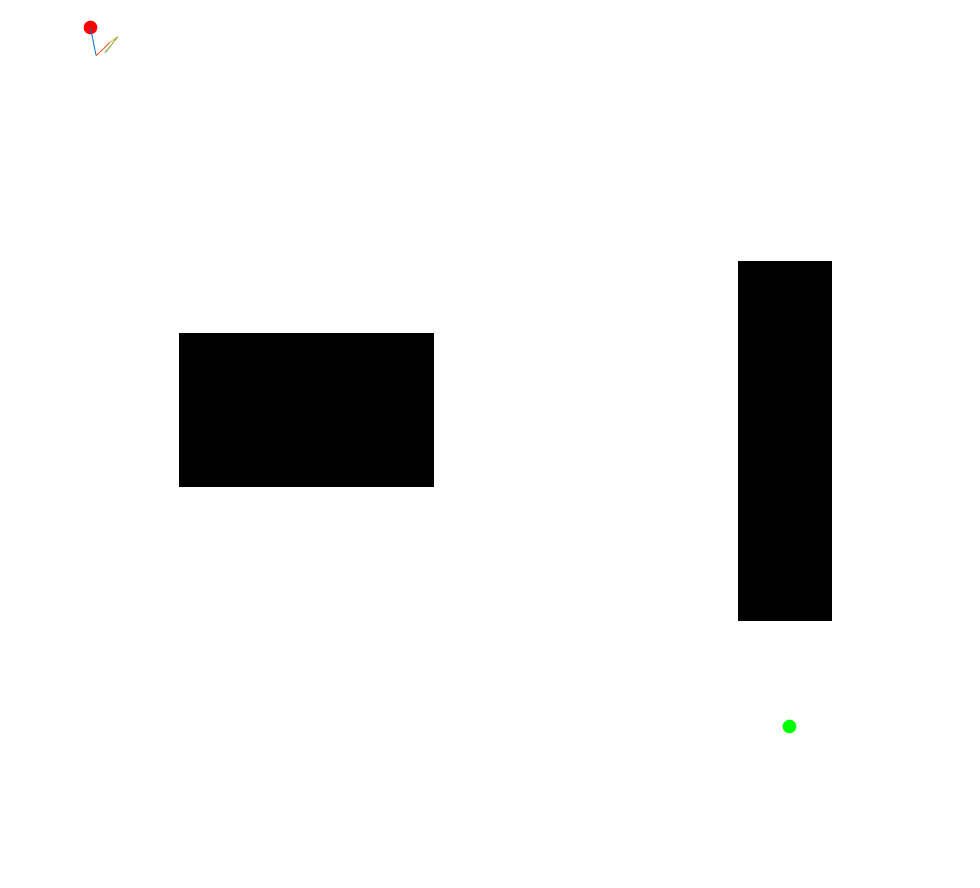

figure(1);
ImpRgb=imread('newmap.png');
Imp=rgb2gray(ImpRgb);
imshow(Imp)
xL=size(Imp,1);%地图x轴长度
yL=size(Imp,2);%地图y轴长度
hold on
plot(x_I, y_I, 'ro', 'MarkerSize',10, 'MarkerFaceColor','r');
plot(x_G, y_G, 'go', 'MarkerSize',10, 'MarkerFaceColor','g');% 绘制起点和目标点
count=1;
x_rand = []; y_rand = [];
x_near = []; y_near = [];
x_new = []; y_new = [];
for iter = 1:3000
    %x_rand=[]; y_rand=[];
    x_rand= randi(xL); y_rand= randi(yL);
    %Step 1: 在地图中随机采样一个点x_rand
    %提示：用（x_rand(1),x_rand(2)）表示环境中采样点的坐标
    
    %x_near=[]; y_near=[];
    %Step 2: 遍历树，从树中找到最近邻近点x_near 
    %提示：x_near已经在树T里
    %size = size(T.v);
    %tmp_x = T.v(1).x; tmp_y = T.v(1).y;
    tmp_dis = 1000;
    parent_i = 0;
    for i = 1:1:count
        dis = sqrt((x_rand - T.v(i).x)^2 + (y_rand-T.v(i).x)^2);
        if dis < tmp_dis
            x_near = T.v(i).x; y_near = T.v(i).y;
            tmp_dis = dis;
            parent_i = i;
        end
    end
    
    %x_new=[]; y_new=[];
    %Step 3: 扩展得到x_new节点
    %提示：注意使用扩展步长Delta
    x_new = Delta/tmp_dis*(x_rand- x_near);
    y_new = Delta/tmp_dis*(y_rand- y_near);
    
    %检查节点是否是collision-free
    if ~collisionChecking([x_near y_near],[x_new y_new],Imp) 
        continue;
    end
    
    count=count+1;
    
    %Step 4: 将x_new插入树T 
    %提示：新节点x_new的父节点是x_near
    T.v(count).x = x_new;
    T.v(count).y = y_new;
    T.v(count).xPrev = x_near;
    T.v(count).yPrev = y_near;
    T.v(count).dist = Delta + T.v(parent_i).dist;
    
    %Step 5:检查是否到达目标点附近 
    %提示：注意使用目标点阈值Thr，若当前节点和终点的欧式距离小于Thr，则跳出当前for循环
    plot([x_new x_near], [y_new y_near]);
    hold on
    
    if (sqrt((x_new - x_G)^2 + (y_new-y_G)^2) < Thr)
        break;
    end
    
   %Step 6:将x_near和x_new之间的路径画出来
   %提示 1：使用plot绘制，因为要多次在同一张图上绘制线段，所以每次使用plot后需要接上hold on命令
   %提示 2：在判断终点条件弹出for循环前，记得把x_near和x_new之间的路径画出来
   
   pause(0.1); %暂停0.1s，使得RRT扩展过程容易观察
end

## 路径已经找到，反向查询

if iter < 2000
    path.pos(1).x = x_G; path.pos(1).y = y_G;
    path.pos(2).x = T.v(end).x; path.pos(2).y = T.v(end).y;
    pathIndex = T.v(end).indPrev; % 终点加入路径
    j=0;
    while 1
        path.pos(j+3).x = T.v(pathIndex).x;
        path.pos(j+3).y = T.v(pathIndex).y;
        pathIndex = T.v(pathIndex).indPrev;
        if pathIndex == 1
            break
        end
        j=j+1;
    end  % 沿终点回溯到起点
    path.pos(end+1).x = x_I; path.pos(end).y = y_I; % 起点加入路径
    for j = 2:length(path.pos)
        plot([path.pos(j).x; path.pos(j-1).x;], [path.pos(j).y; path.pos(j-1).y], 'b', 'Linewidth', 3);
    end
else
    disp('Error, no path found!');
end